# Automatización del Análisis de Datos Solares

Una vez que hemos creado iterativamente nuestro análisis, es útil automatizarlo en forma de una función para poder realizar análisis similares en una variedad de ubicaciones y comparar los resultados.

## Seleccionar una Carpeta de Datos

folderName = "C:\Users\garellan\OneDrive - MathWorks\Documents - LATAM Team\2025\000_Events & Visits 2025\03_24_UNA\Codigo y datos\SolarData";

Para seleccionar una carpeta de forma interactiva, descomenta la primera línea y comenta la segunda línea.

allFileNames = dir(fullfile(folderName,'*Daily.xlsx'));

addpath("HelperFunctions\","SolarData\")

## Ejecutar Análisis en Todos los Archivos Excel en la Carpeta

#### Preasignando variables

coeffs = zeros(length(allFileNames),4);
stationName = cell(length(allFileNames),1);

tic

#### Recorriendo todos los archivos Excel

BennettValleyDaily.xlsx


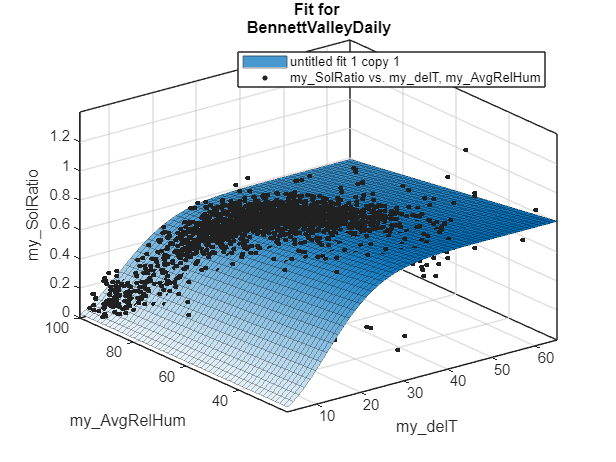

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8645  (0.8408, 0.8881)
       b =    0.003233  (0.002869, 0.003597)
       c =    0.003573  (0.002362, 0.004785)
       n =       1.987  (1.866, 2.108)
58.101 percent of data points were within estimated bounds


BishopDaily.xlsx


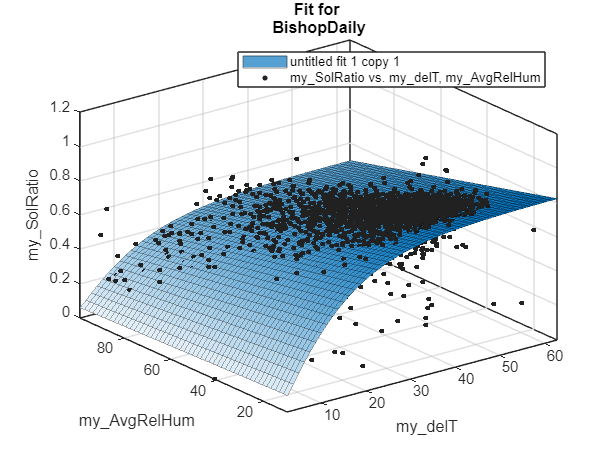

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8593  (0.8442, 0.8744)
       b =    0.004283  (0.003951, 0.004615)
       c =     0.04474  (0.0254, 0.06408)
       n =       1.185  (1.036, 1.335)
87.945 percent of data points were within estimated bounds


BrentwoodDaily.xlsx


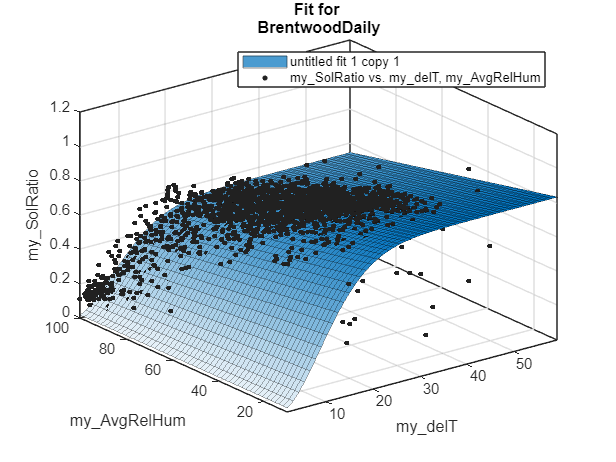

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8621  (0.8452, 0.8789)
       b =    0.003723  (0.003444, 0.004003)
       c =    0.009272  (0.006213, 0.01233)
       n =       1.817  (1.692, 1.941)
54.469 percent of data points were within estimated bounds


DavisDaily.xlsx


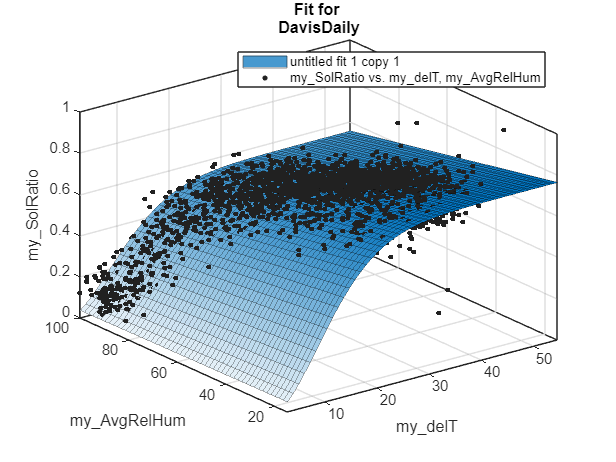

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.7995  (0.786, 0.8129)
       b =    0.003053  (0.002777, 0.003328)
       c =     0.01015  (0.007715, 0.01258)
       n =       1.757  (1.666, 1.847)
63.260 percent of data points were within estimated bounds


OxnardDaily.xlsx


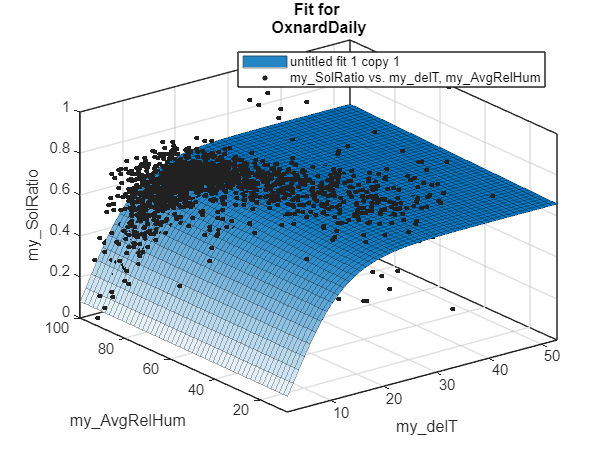

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.6555  (0.632, 0.6789)
       b =  -0.0004726  (-0.001104, 0.0001583)
       c =     0.04839  (0.0345, 0.06228)
       n =       1.389  (1.251, 1.526)
84.848 percent of data points were within estimated bounds


PomonaDaily.xlsx


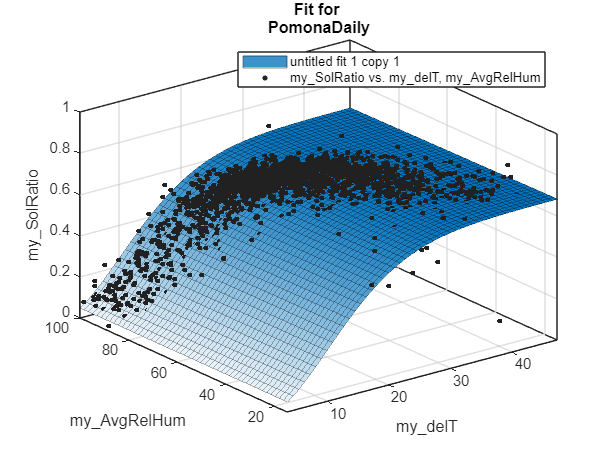

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.6846  (0.6684, 0.7008)
       b =   0.0002375  (-0.0002207, 0.0006957)
       c =    0.006656  (0.005085, 0.008226)
       n =       1.825  (1.734, 1.916)
75.000 percent of data points were within estimated bounds


SantaBarbaraDaily.xlsx


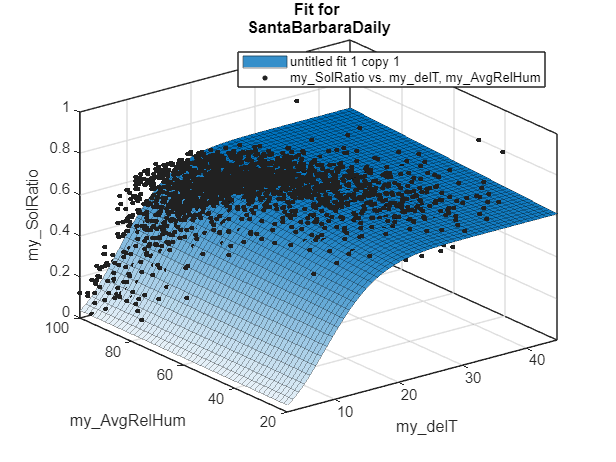

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.5953  (0.575, 0.6155)
       b =   -0.001223  (-0.001826, -0.0006194)
       c =    0.006517  (0.004574, 0.00846)
       n =       2.048  (1.924, 2.172)
82.203 percent of data points were within estimated bounds


SantaRosaDaily.xlsx


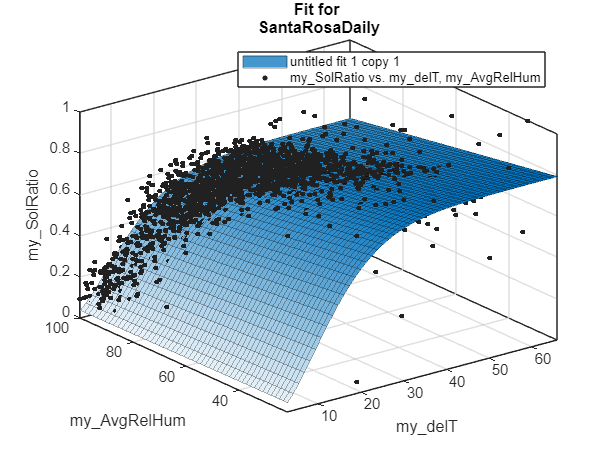

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8403  (0.8152, 0.8654)
       b =    0.002654  (0.002274, 0.003035)
       c =     0.01108  (0.008442, 0.01371)
       n =       1.619  (1.53, 1.708)
53.297 percent of data points were within estimated bounds


UCRiversideDaily.xlsx


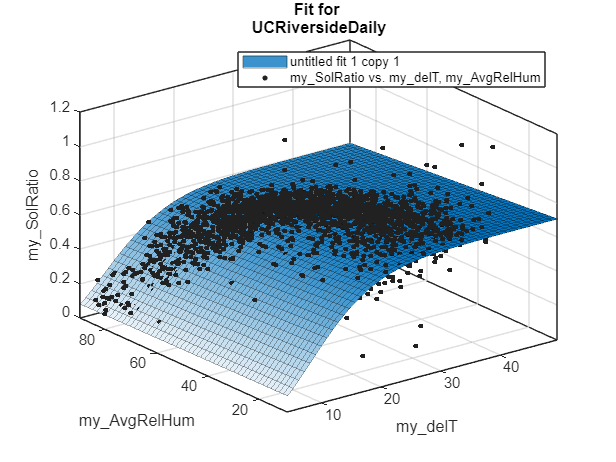

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =       0.714  (0.7029, 0.7252)
       b =    0.001847  (0.001522, 0.002172)
       c =     0.01078  (0.007633, 0.01392)
       n =       1.776  (1.663, 1.89)
76.099 percent of data points were within estimated bounds


WindsorDaily.xlsx


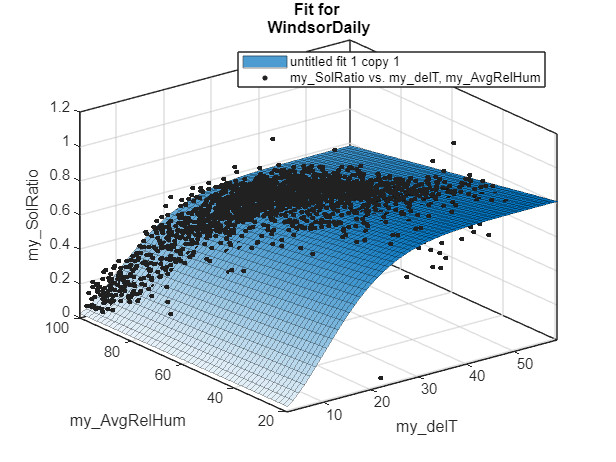

     General model:
     model(delT,H) = a*(1-b*H)*(1-exp(-c*(delT)^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8566  (0.836, 0.8771)
       b =    0.003213  (0.002904, 0.003523)
       c =    0.007859  (0.005888, 0.009831)
       n =       1.736  (1.645, 1.828)
57.064 percent of data points were within estimated bounds


for ii = 1:length(allFileNames)
   
    % Display file processing
    disp(allFileNames(ii).name)
    
    % Create full file name and extract name of station
    fileName = fullfile(folderName,allFileNames(ii).name);
    [~, stationName{ii,1}, ~] = fileparts(allFileNames(ii).name);
    
    % Run Analysis Function
    [DayOfYear_test,EstRad,PredInt,SolRatio_test,model] = SolarAnalysisFcn(fileName);


    % Extract Coefficents
    coeffs(ii,:) = coeffvalues(model);
    
end

toc

Elapsed time is 5.174460 seconds.


## Escribimos los resultados en un archivo de Excel

VarNames = {'Station','a','b','c','n'};
T = table(stationName,coeffs(:,1),coeffs(:,2),coeffs(:,3),coeffs(:,4),'VariableName',VarNames);
writetable(T,'SolarFitResults.xlsx')

*Copyright 2025 The MathWorks, Inc.*